**Equivalent nodal forces**

As an example, we calculate the first component of the vector of equivalent nodal forces  **F** due to a trapezoidal load with intensities  *p1* and  *p2* .

syms z
syms X,L

L = 1

L=1;
N_1 = 1 - 3 * z^2 + 2 * z^3

$$N\_1 = 2\,z^{3}-3\,z^{2}+1$$

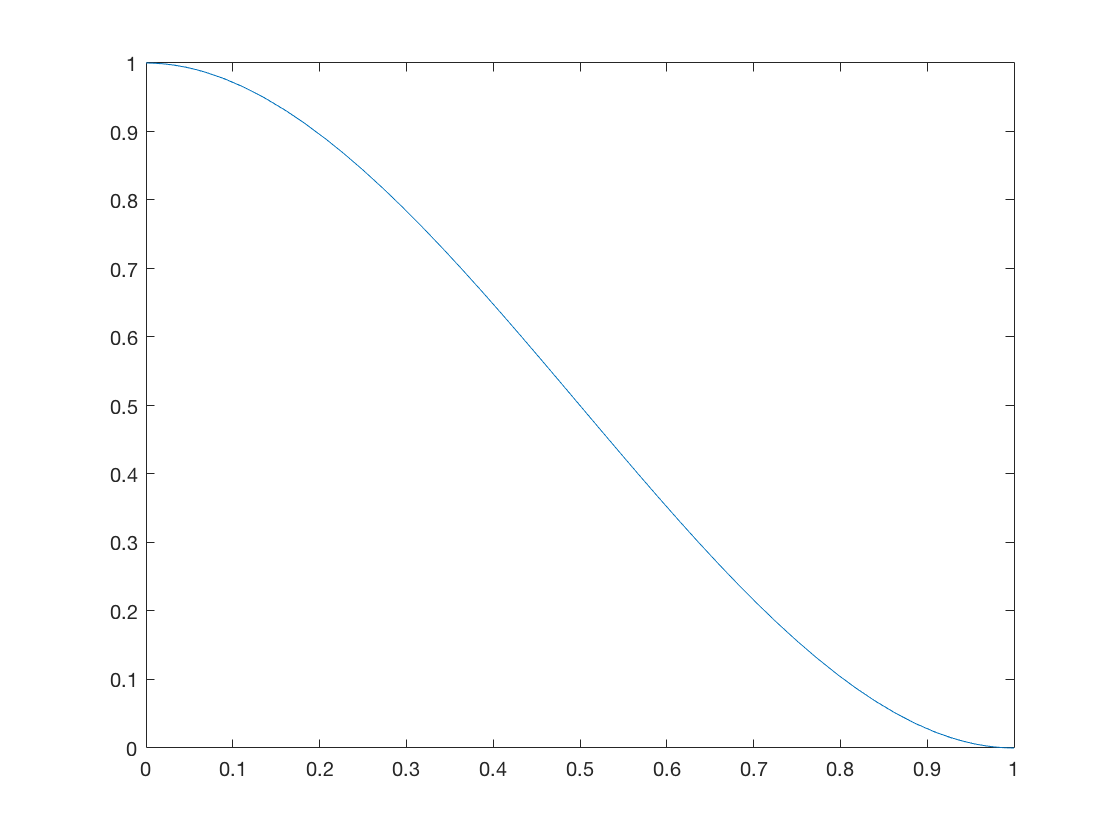

figure
fplot(N_1, [0, 1])


N_3 = 3 * z^2 - 2 * z^3

$$N\_3 = 3\,z^{2}-2\,z^{3}$$

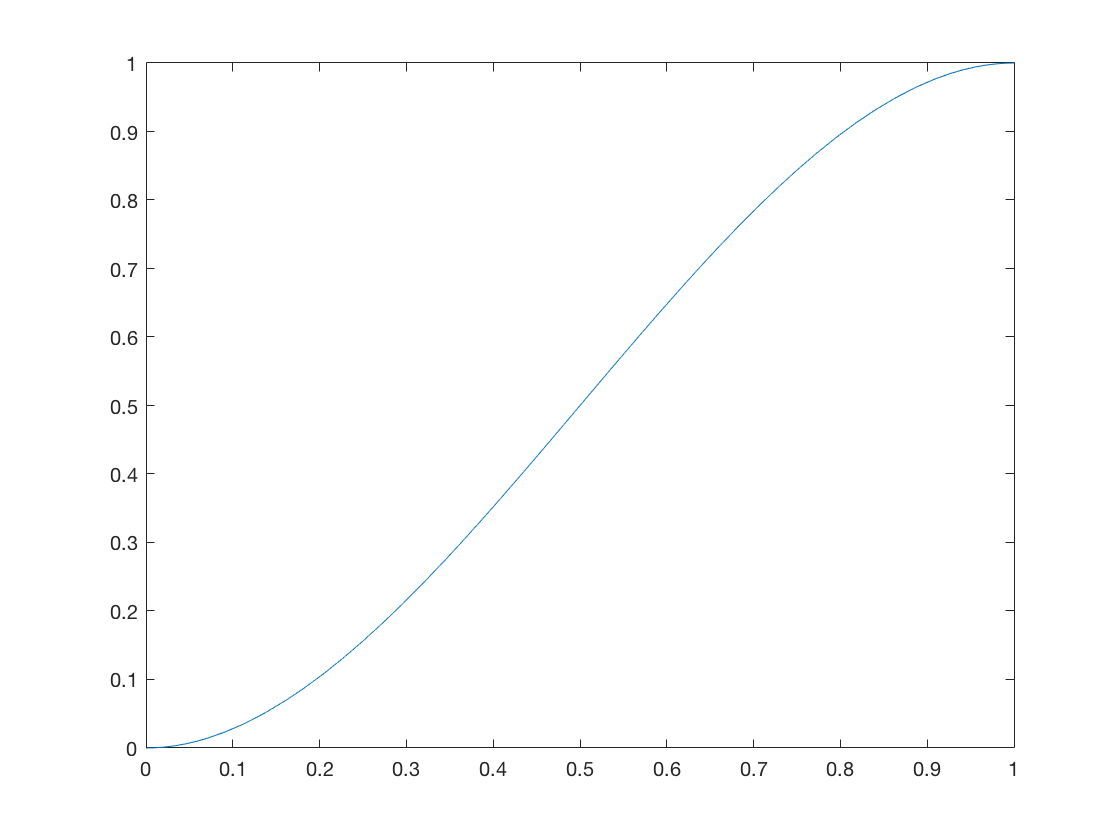

figure
fplot(N_3, [0, 1])

N_2 = L * z * (z - 1)^2

$$N\_2 = z\,{\left(z-1\right)}^{2}$$

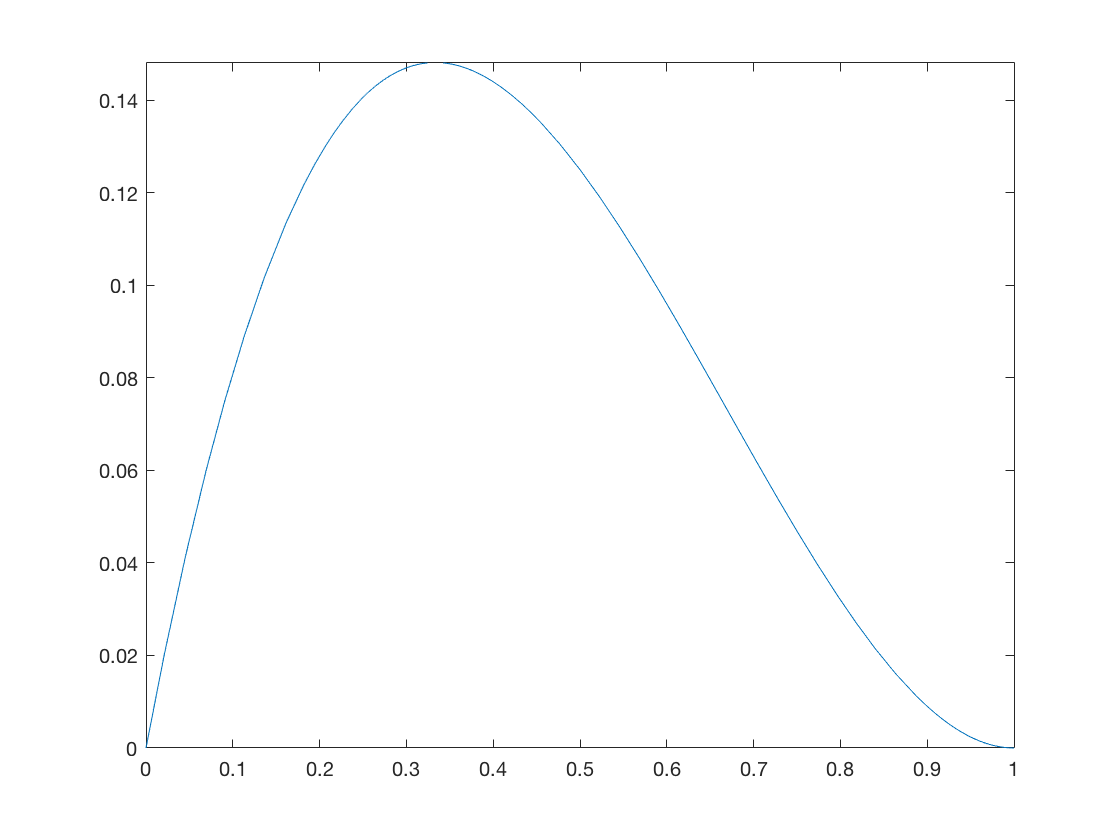

figure
fplot(N_2, [0, 1])

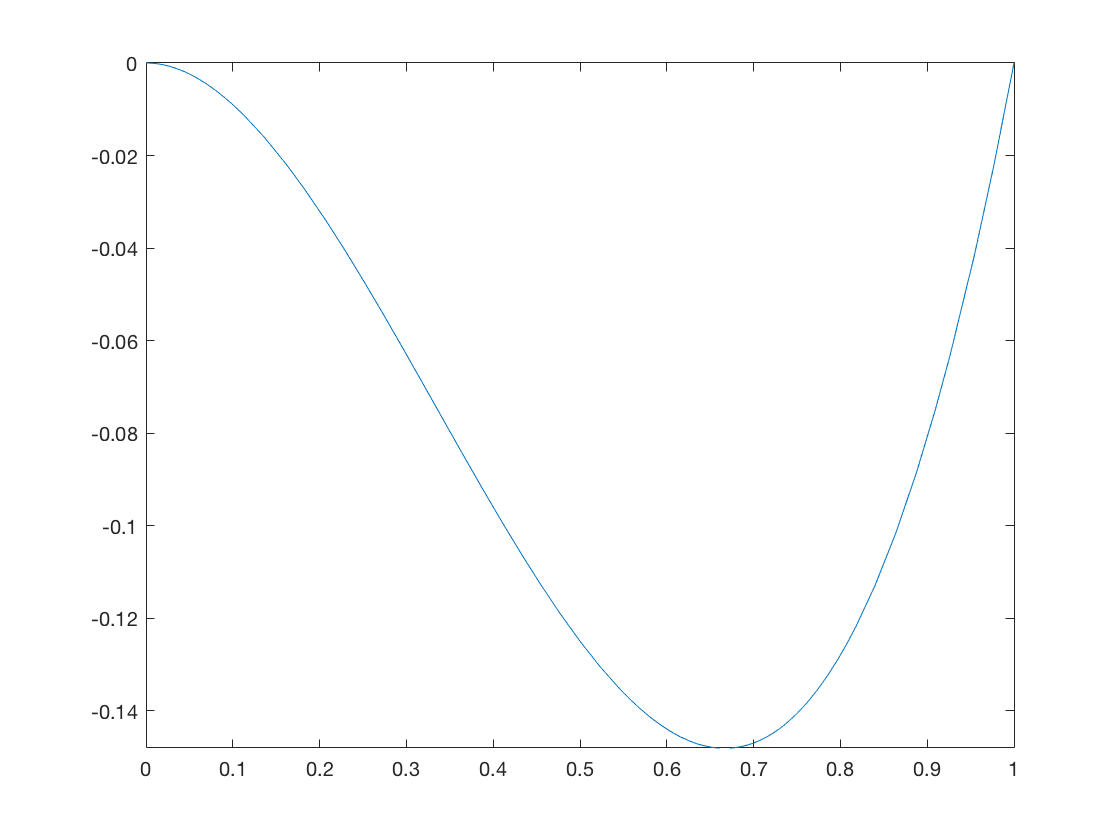

N_4=-L*(z^2-z^3);
figure
fplot(N_4, [0, 1])

Works in real coordinate


N_1 = subs(N_1, z, X/L)

$$N\_1 = 2\,X^{3}-3\,X^{2}+1$$

N_2 = subs(N_2, z, X/L)

$$N\_2 = X\,{\left(X-1\right)}^{2}$$

N_3 = subs(N_3, z, X/L)

$$N\_3 = 3\,X^{2}-2\,X^{3}$$

N_4 = subs(N_4, z, X/L)

$$N\_4 = X^{3}-X^{2}$$


int(N_1, X)

$$ans = \frac{X^{4}}{2}-X^{3}+X$$


int(N_1, X, sym(0), L)

$$ans = \frac{1}{2}$$


N = [N_1; N_2; N_3; N_4]

$$N = \left(\begin{array}{c} 2\,X^{3}-3\,X^{2}+1\\ X\,{\left(X-1\right)}^{2}\\ 3\,X^{2}-2\,X^{3}\\ X^{3}-X^{2} \end{array}\right)$$


int(N, X)

$$ans = \left(\begin{array}{c} \frac{X^{4}}{2}-X^{3}+X\\ \frac{X^{2}\,\left(3\,X^{2}-8\,X+6\right)}{12}\\ -\frac{X^{3}\,\left(X-2\right)}{2}\\ \frac{X^{3}\,\left(3\,X-4\right)}{12} \end{array}\right)$$


syms Feq
Feq = symhold('p1*int(N, X, 0, L) + (p2 - p1)*int((X*N)/L, X, 0, L)')

$$Feq = p_{1}\,\int N\mathrm{d}X+\left(p_{2}-p_{1}\right)\,\int \frac{X\,N}{L}\mathrm{d}X$$

Finally

syms p1 p2
Feq = p1 * int(N, X, sym(0), L) + (p2 - p1) * int((X * N)/L, X, sym(0), L)

$$Feq = \left(\begin{array}{c} \frac{7\,p_{1}}{20}+\frac{3\,p_{2}}{20}\\ \frac{p_{1}}{20}+\frac{p_{2}}{30}\\ \frac{3\,p_{1}}{20}+\frac{7\,p_{2}}{20}\\ -\frac{p_{1}}{30}-\frac{p_{2}}{20} \end{array}\right)$$


simplify(Feq)

$$ans = \left(\begin{array}{c} \frac{7\,p_{1}}{20}+\frac{3\,p_{2}}{20}\\ \frac{p_{1}}{20}+\frac{p_{2}}{30}\\ \frac{3\,p_{1}}{20}+\frac{7\,p_{2}}{20}\\ -\frac{p_{1}}{30}-\frac{p_{2}}{20} \end{array}\right)$$

Special case were p1=p2=p

syms p
Feq = subs(subs(Feq, p1, p), p2, p)

$$Feq = \left(\begin{array}{c} \frac{p}{2}\\ \frac{p}{12}\\ \frac{p}{2}\\ -\frac{p}{12} \end{array}\right)$$

 That's all

## Local Functions

## Helpers

function h = symhold(exprstring)
h = evalin(symengine, ['hold(' exprstring ' )']);
end